Clearing data

clc
clearvars;

Parameters

 %% Parameters
    cases = 100;
    count = 0;
    %%variances 
    N=[0 0.01 0.05 0.1];
    
    producers  = 5;
    consumers = 1;
    Bus = 5;
    

Deterministic impedance OPF

%% standard OPF
    %%resistances r, reactences x and line susceptance b
    r = [0.00281 0.00304 0.00064 0.00108 0.00297 0.00297];
    x = 10*r;
    b = [0.00712 0.00658 0.03126 0.01852 0.00674 0.00674];
    
    r_ = zeros(cases,length(r));
    x_ = zeros(cases,length(x));
    b_ = zeros(cases,length(b));
    
    mpc_det = loadcase(case5);
    mpc_det.branch(:,3) = r'; %%r values of branches
    mpc_det.branch(:,4) = x'; %%x values of branches
    mpc_det.branch(:,5) = b'; %%b values of branches
    
    results = runopf(mpc_det); %%running the opf on our case


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           

    
    %% here, impedance is perfectly known 
    %%results.gen(:,2) yields active power from perfectly known impedance
    %%results.gen(:,3) yields reactive power from perfectly known impedance
    P_perfimped = results.gen(:,2);
    Q_perfimped = results.gen(:,3);
    
    %we will show that running a PF on a deterministic OPF will yield
    %same/similar results
    mpcpf_det = loadcase(case5);
        mpcpf_det.branch(:,3) = r';
        mpcpf_det.branch(:,4) = x';
        mpcpf_det.branch(:,5) = b';
        
        mpcpf_det.gen(:,2)  =results.gen(:,2);
        mpcpf_det.gen(:,3)  =results.gen(:,3);
        
        mpcpf_det.bus(:,3)  =results.bus(:,3);
        mpcpf_det.bus(:,4)  =results.bus(:,4);
        
        results_pf = runpf(mpcpf_det);


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

        
        %%we solved the OPF and input the results into a standard PF
        %%problem. 
        
        gen_power = results_pf.gen(:,2);
        A = gen_power - P_perfimped; %should get a zero vector
    
    results.bus(:,3); %consumption active    [P]
    results.bus(:,4); %consumption reactive [Q]
    active_bus = results.bus(:,3);
    reactive_bus = results.bus(:,4);
    

Declaring variables

    %% variables
    gen_power        = zeros(producers,cases);
    gen_power_test   = zeros(producers,cases);
    bus_power        = zeros(producers,cases);
    
    reallosses = zeros(producers,cases);
    reactivelosses = zeros(producers,cases);
    losses             = zeros(producers,cases);
    l = zeros(producers,cases);
    
    %using det OPF generator values as production powers
    prod_active = mpc_det.gen(:,2);
    prod_reactive = mpc_det.gen(:,3);

    
   

Initialzing stochastic impedance case


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.07 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17551.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17873.55 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1019.0             374.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15380.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    964.3             455.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1009.4             414.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18015.50 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1012.9             384.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.9             370.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15131.40 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1010.7             387.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15677.04 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1028.9             398.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20755.47 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.6             348.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             352.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 16363.94 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1011.0             365.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.2             383.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 68 iterations.

>>>>>  Did NOT converge (0.18 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.9             399.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15262.48 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.2             387.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.1             391.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20147.50 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.3             352.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             354.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15273.56 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    996.7             388.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.0             390.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18654.86 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    993.6             371.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             361.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.06 seconds
Objective Function Value = 14717.36 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    996.9             403.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17469.80 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    987.4             429.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.8             368.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15332.27 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             376.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.1             392.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14949.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    991.0             387.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             393.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15055.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.2             413.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19503.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.9             367.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13900.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    969.7             418.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.8             399.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19601.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.4             352.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.6             357.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15333.40 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    994.7             425.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.9             389.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19996.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    984.9             370.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             352.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15220.43 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1013.7             397.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14747.93 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    997.9             433.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16745.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    991.4             389.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.4             374.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18669.98 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    990.0             395.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             360.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19187.75 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1012.6             385.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.8             389.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 17381.67 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    987.6             395.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.8             369.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20284.79 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1010.6             352.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             355.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15603.70 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1026.5             361.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19999.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    985.2             374.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             353.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15047.05 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.9             365.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15537.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1015.8             380.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             393.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16642.90 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1010.8             410.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.8             409.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18031.04 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    994.1             391.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.5             365.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19022.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1015.1             364.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             363.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19811.15 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             362.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.5             356.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15218.84 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1013.6             380.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001         0         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17960.74 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1021.6             345.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000         0         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14136.94 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    977.6             431.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             398.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Did not converge in 150 iterations.

>>>>>  Did NOT converge (0.37 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.9             400.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003         0         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003         0         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15872.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1032.0             364.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.3             394.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000         0         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000         0         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16941.61 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.9             413.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.5             376.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000         0         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001         0         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15414.01 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1020.1             375.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000         0         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000         0         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14368.11 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    984.2             427.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             397.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016         0         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826         0         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19683.25 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.8             353.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000         0         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001         0         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16462.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1029.3             340.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.6             387.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000         0         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466         0      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18551.86 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    986.3             379.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.5             385.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000         0         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000      


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17435.28 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1014.5             400.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1009.0             411.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000         0
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20216.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.0             346.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             354.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16804.50 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             375.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.7             378.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16885.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             396.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.0             401.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15624.96 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1027.2             397.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15101.38 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1009.7             364.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18784.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    992.5             400.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.8             388.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21422.41 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             360.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.3             363.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20356.42 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1019.9             355.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.6             356.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18977.81 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             350.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             361.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19261.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.3             368.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.9             360.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19308.27 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1016.6             375.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.1             361.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14808.83 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.0             408.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15031.37 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             392.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15505.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1023.2             369.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15134.88 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1010.8             398.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14765.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.5             397.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15919.61 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             379.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.6             386.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18489.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1011.1             365.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.5             366.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17520.09 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1015.0             358.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.3             374.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20521.43 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.3             355.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             352.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14767.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.6             400.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15204.57 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1013.2             381.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16453.95 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    999.0             374.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.8             379.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13380.04 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    952.3             393.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.9             400.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14351.47 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    984.7             418.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             398.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20561.95 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1011.8             356.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             354.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18433.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             352.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.3             364.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14020.92 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    950.6             385.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.1             391.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19433.20 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    975.9             370.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             353.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15618.54 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1027.0             392.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15224.00 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1013.6             358.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             396.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15025.60 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             400.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.06 seconds
Objective Function Value = 15049.55 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.0             413.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21101.58 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             346.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             351.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17688.83 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    979.6             423.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18421.93 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.5             366.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.3             364.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 16767.22 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             374.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.7             377.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19909.67 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.3             349.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.6             356.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16682.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.9             398.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.0             400.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.06 seconds
Objective Function Value = 14081.23 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    975.7             407.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.8             398.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14653.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    981.9             368.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             393.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15024.95 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             372.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16006.73 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    995.3             409.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.1             382.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 25 iterations.

>>>>>  Did NOT converge (0.08 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.9             389.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16983.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1029.9             368.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.0             391.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.06 seconds
Objective Function Value = 14979.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.6             362.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16692.22 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1016.2             392.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.1             382.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18609.24 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             374.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.7             388.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17392.98 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             392.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16069.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1017.4             384.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.7             388.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13782.66 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    965.8             389.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.8             399.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23650.59 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1017.7             354.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             344.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 22303.19 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.3             365.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.6             346.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             332.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    0.0000    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.1             331.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584    0.0000   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15543.69 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    933.2             339.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             371.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268   -0.0000  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19938.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1009.3             377.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999  -81.6095    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21070.46 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1015.8             425.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             352.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0001    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24545.89 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1036.5             320.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.5             345.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 13670.19 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    906.7             619.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.4             384.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0000  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19666.90 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    961.0             323.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.9             350.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001  -37.5708    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20482.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1103.2             282.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19274.70 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    976.8             371.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             354.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 24870.86 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    973.8             354.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             336.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000   -0.0000  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 12549.64 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    834.8             617.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.6             377.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101  -26.7358    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 23512.05 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1064.0             397.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             350.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             333.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14849.40 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             355.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14679.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    988.4             431.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.4             395.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001    0.0001    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19231.32 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    995.0             333.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             358.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 21473.16 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    991.0             397.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.7             347.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20992.74 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1100.8             369.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.7             368.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0000    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0001 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17514.65 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    962.2             462.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             363.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000 -146.2907    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 17848.04 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1016.3             256.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23005.70 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1024.9             438.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.6             347.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 25135.60 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    995.9             311.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 25346.57 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    998.0             408.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0000    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000    0.0000    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24895.83 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    970.6             354.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.5             336.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002    0.0000  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006    0.0001 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15441.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    912.2             347.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.8             368.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002  -39.9999    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795 -169.9999    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18930.50 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    944.1             282.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             351.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19937.59 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             397.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001  -16.9007   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 27406.84 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1070.5             297.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             339.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001   -0.0001    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15929.27 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1017.6             519.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.8             389.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 21412.73 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    961.6             383.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             344.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19844.68 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1167.8             478.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.2             393.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19850.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    988.5             358.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.9             360.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999    0.0000    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999    0.0001    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 17707.24 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    966.8             460.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             362.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998    0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998    0.0000    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16333.10 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    969.4             505.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             373.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16666.99 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    954.6             454.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.7             367.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000   -0.0003    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000   -0.0003    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24293.74 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1022.5             372.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             342.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0000    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19882.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1011.6             496.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18504.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    989.8             400.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.1             361.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.0000   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.1             331.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056   -0.0016    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323   -2.0826    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23126.97 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    964.7             370.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             339.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000    0.0001  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 10981.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    864.0             519.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.4             405.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196  -51.5466    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16334.10 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    945.5             295.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.8             368.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0000   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19611.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    967.8             395.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             351.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001   -0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 25906.63 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             358.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             336.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 9076.12 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    777.6             382.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0            


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.4             405.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19486.25 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    978.9             299.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18999.51 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1068.8             299.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.4             374.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 21296.31 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    987.3             411.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.7             347.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24250.21 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    999.1             402.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 15984.33 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1039.1             288.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.4             395.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20558.91 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1059.1             406.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             362.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16267.78 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1048.6             398.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.4             394.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21292.25 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    955.9             330.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             343.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 8 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             335.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20603.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1015.2             399.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             354.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18507.16 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1065.6             406.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.7             377.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             334.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13236.64 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    947.6             369.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.0             400.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24558.19 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.8             333.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             339.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17650.67 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.5             369.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.9             370.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15514.45 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    904.1             365.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.6             366.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19967.90 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             300.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.5             355.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16872.92 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.0             360.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.7             377.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18407.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             467.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.4             364.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14354.60 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    964.5             400.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.1             391.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14680.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    833.0             379.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.9             389.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20332.97 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    997.4             280.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             353.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14509.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    971.7             395.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.1             392.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19568.46 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    955.3             361.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             350.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23690.93 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    942.8             366.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.5             336.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19449.20 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    988.2             388.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.5             355.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 17825.05 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1019.9             474.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             373.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.1             331.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 33 iterations.

>>>>>  Did NOT converge (0.10 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             352.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14249.07 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    981.3             366.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             398.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19480.12 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    906.4             359.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20562.95 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    918.0             354.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             344.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14399.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    971.5             322.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.1             402.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20685.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             347.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             352.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 99 iterations.

>>>>>  Did NOT converge (0.25 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.0             381.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 23052.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1047.1             325.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.9             350.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18865.39 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    999.0             406.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.1             362.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16333.03 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.3             421.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.2             383.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             334.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21086.42 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1053.4             374.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.8             358.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15155.07 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    920.5             440.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.1             372.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 11586.57 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    885.5             504.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.2             403.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14191.22 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    935.5             419.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.4             385.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19949.91 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    865.0             379.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 26505.17 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    979.8             368.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             334.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23528.88 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1010.2             297.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             343.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19877.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    941.6             439.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.9             349.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             332.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23213.47 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1056.1             369.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             350.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18412.31 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    985.8             415.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.9             370.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0001    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14614.17 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    993.5              85.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             397.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0000    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20363.43 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1053.2             218.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.2             362.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000    0.0000    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001    0.0001    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 14316.04 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    672.5             204.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003    9.3778   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    1.7584 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 22560.27 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1045.0             288.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             351.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000   -0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000 -101.6268 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20739.38 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1012.0             311.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             353.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000  -39.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001 -169.9999    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16664.09 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    978.6             528.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.2             373.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 12 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.8             349.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136    0.0000    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             333.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779    0.0001    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19534.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    887.9             501.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.0             341.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0000    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17593.40 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    885.7             252.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.8             349.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    0.0000    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    0.0001    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             333.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635    0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744    0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17889.03 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    923.2             380.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             353.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000   -0.0000    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -162.2101    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13115.87 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    700.3             304.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.7             347.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21158.32 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1059.9             335.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.9             359.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    4.0088    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.7517    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.0             331.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914    0.5322    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0998    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21832.51 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1029.1             259.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             351.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 18520.88 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    919.2             497.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.8             349.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000    0.0001   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23240.71 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    934.3             361.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999   -0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999   -0.0000    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 13134.82 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    898.4              34.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.4             394.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000    0.0000   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001    0.0001   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23087.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    897.6             327.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.0001    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220   -0.0013    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 13 iterations.

>>>>>  Did NOT converge (0.05 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             334.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.3556    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0667    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 24489.34 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    927.3             195.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             333.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    0.0000    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.1             382.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.0000    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0000    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.7             347.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0001   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19645.95 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    909.8             389.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0001    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000   -0.0001    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14143.65 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    912.9             407.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.0             380.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002    0.0000   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287    0.0000   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.0             340.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013   -0.0002   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752   -0.0006  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 12 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.9             329.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500   -0.0002    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366  -37.3795    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19127.24 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.4             330.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             360.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000    0.0001    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 16 iterations.

>>>>>  Did NOT converge (0.05 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.0             330.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0001    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21994.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    989.8             398.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.5             345.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000    0.0000   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000    0.0001  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             354.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744   -0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576  -39.3939    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 22098.06 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    915.0             410.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    0.0000    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.0000    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 13 iterations.

>>>>>  Did NOT converge (0.07 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.8             339.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 22008.77 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    968.9             372.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -39.9999  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20156.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1056.0             384.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.4             365.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749  -39.9998   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999 -169.9998 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 11871.13 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    799.6             356.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.6             377.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -162.7891    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 8 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             336.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568    0.0000    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 41 iterations.

>>>>>  Did NOT converge (0.12 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0001    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 24953.24 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    944.8             195.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             334.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0001    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 14571.16 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    992.0             584.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.7             397.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 12202.82 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    913.1             320.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1008.3             403.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    3.9056    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    0.7323    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             338.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 25728.31 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    975.3             236.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             335.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000  -16.8196    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 100 iterations.

>>>>>  Did NOT converge (0.26 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.0             340.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000    0.0000    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999    0.0000    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.3             333.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19928.96 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    932.8             354.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.4             345.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000    0.0000   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001    0.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 24426.52 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    908.8             351.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             332.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004   -0.0001
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 23680.60 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1023.2             287.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             350.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 13 iterations.

>>>>>  Did NOT converge (0.05 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.8             339.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17565.69 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    880.0             409.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.6             377.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.27 seconds
Objective Function Value = 22904.31 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1031.0             380.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.7             348.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 16808.56 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1066.6             427.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.3             394.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 17995.34 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1016.0             176.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.9             370.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17112.03 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1018.8             123.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1005.7             378.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 9286.55 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    814.4             114.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0            


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1009.4             415.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20382.26 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    907.0             239.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.0             340.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.9             330.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24874.65 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1096.4             384.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.0             350.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 10313.85 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    801.1             764.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.6             396.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             339.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 25765.30 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    989.2             270.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.5             336.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20583.05 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    984.9             294.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.9             350.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 25611.10 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1033.7             404.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             340.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21578.97 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1099.7             245.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.4             364.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20740.37 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.2             448.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             352.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 19823.63 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    959.3             173.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.8             349.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             338.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 22582.35 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1047.3             475.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.1             351.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 23903.15 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    933.2             266.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 23853.34 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    894.8             391.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.2             332.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21506.32 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    949.5             456.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.1             342.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 17990.50 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    890.7             148.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.6             347.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 24690.23 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    965.9             396.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.5             336.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.06 seconds
Objective Function Value = 22653.46 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    902.3             360.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             335.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 42 iterations.

>>>>>  Did NOT converge (0.12 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.2             382.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 27375.63 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1076.3             302.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.9             340.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23561.84 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1030.2             297.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.5             346.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.1             332.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 25069.67 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1164.0             288.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.0             360.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)


Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 26871.76 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.9             304.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.4             335.1
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 19407.18 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    975.0             437.9
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.3             353.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20539.84 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    928.4             545.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             343.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 10 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.3             343.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20258.92 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1000.7             436.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.7             357.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 11 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.1             331.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 15599.14 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1026.3             508.4
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1007.5             395.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 23130.02 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    997.3             328.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.2             343.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 18363.92 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1096.6             526.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1006.6             387.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 27167.44 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1047.1             250.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.7             337.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 21530.24 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    937.1             367.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.0             341.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 22850.16 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1095.1             352.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.8             358.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 20526.79 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)    856.1             422.0
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.5             335.8
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Numerically Failed

Did not converge in 9 iterations.

>>>>>  Did NOT converge (0.04 seconds)  <<<<<




MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1001.6             337.5
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.04 seconds
Objective Function Value = 22788.00 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.6             366.7
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1002.4             345.2
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.


MATPOWER Version 6.0, 16-Dec-2016 -- AC Optimal Power Flow
MATPOWER Interior Point Solver -- MIPS, Version 1.2.2, 16-Dec-2016
 (using built-in linear solver)
Converged!

Converged in 0.05 seconds
Objective Function Value = 20222.23 $/hr
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1004.6             206.3
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0           


MATPOWER Version 6.0, 16-Dec-2016 -- AC Power Flow (Newton)

Newton's method power flow converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity    1530.0       -1147.5 to 1147.5
Generators         5     On-line Capacity      1530.0       -1147.5 to 1147.5
Committed Gens     5     Generation (actual)   1003.4             354.6
Loads              3     Load                  1000.0             328.7
  Fixed            3       Fixed               1000.0             328.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0
Shunts         

reallosses =     0.0000    0.0000   -0.0003   -0.0000    0.0000    0.0000    1.5245    3.2724  -43.6156   -0.0001    0.0000    6.2635   -0.0000  -39.9999    0.0000    2.3914   -0.0000    0.0000  -39.9999    0.0000   -0.0004   -0.8961    0.0000   12.3382    0.4908    0.0000   -0.0002  -53.2013  -25.7500    0.0000  -41.7843    0.0000  -44.5744    0.0000    1.1677    0.0000  -18.4749   -0.0000  -49.9033    0.0000    0.0000    0.0000    0.0000    8.7123    0.0000  -40.0000  -46.0373    0.0000   -0.0004    1.3214
    0.0000    0.0001 -169.9999    0.0000    0.0001    0.0000    0.2859    0.6136 -170.6779  -24.6641    0.0001    1.1744   -0.0000 -169.9999    0.0000    0.4484    0.0000    0.0000 -169.9999    0.0001  -56.7220  -19.8552    0.0001    2.3135    0.0921    0.0000  -44.2287 -172.4752  -31.0366    0.0000 -170.3345    0.0000 -170.8576    0.0001    0.2190    0.0000 -169.9999  -60.0707 -171.8568  -34.8842    0.0000    0.0000    0.0001    1.6336    0.0000 -169.9999 -171.1319    0.0001 -158.

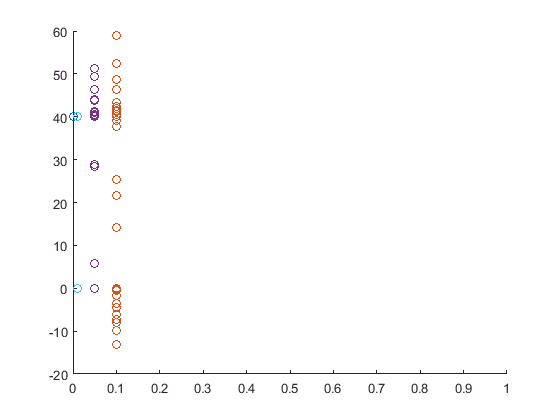

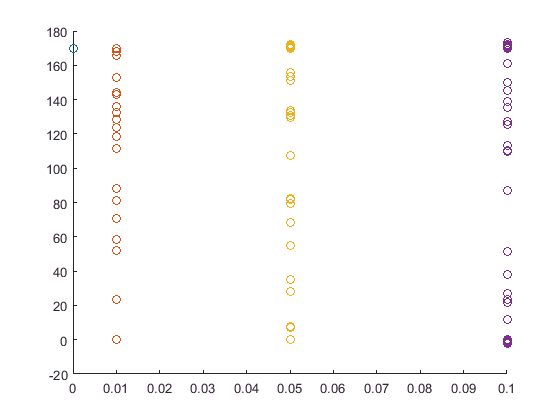

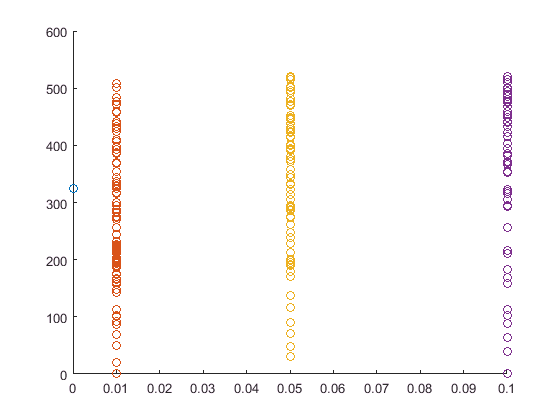

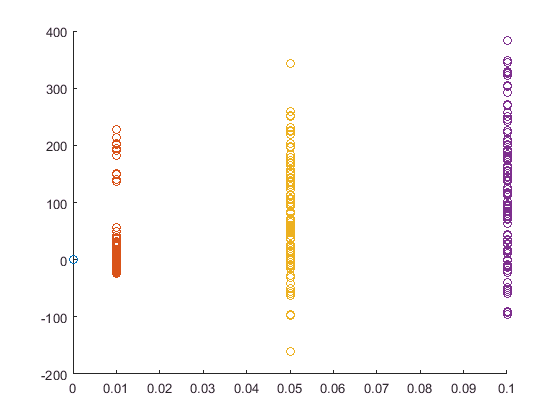

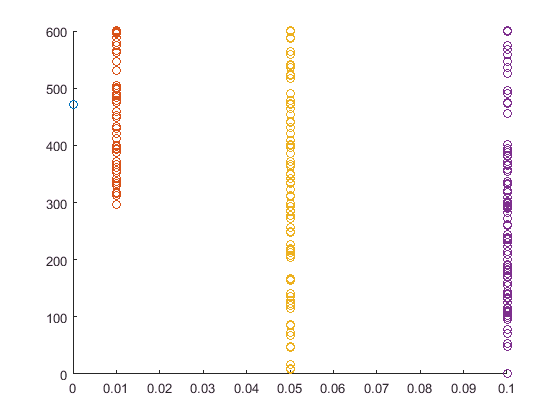

 %% OPF>Power values>PF>error
   
%%stochastic impedances with variance values from N
for k = 1:length(N)
    for i = 1:cases
        r_ = normrnd(r,N(k));
        x_ = normrnd(x,N(k));
        b_ = normrnd(b,N(k));  %stochastic impedances
        %%% OPF
        mpc = loadcase(case5);    %loading case 5
        mpc.branch(:,3) = r_';   %substituting stochastic impedance values
        mpc.branch(:,4) = x_';
        mpc.branch(:,5) = b_';
        
        results = runopf(mpc);  %OPF
        a = results.gen(:,2);
        gen_power_test(:,i)= a;  %for case i, we store generator results
        
        %%PF for the data generated by the OPF on stochastic impedances
        mpcpf = loadcase(case5);
        mpcpf.branch(:,3) = r';  %we will input the deterministic impedances
        %along with power values generated in the stochastic OPF
        mpcpf.branch(:,4) = x';
        mpcpf.branch(:,5) = b';
        
        mpcpf.gen(:,2)  =results.gen(:,2);
        mpcpf.gen(:,3)  =results.gen(:,3);
        
        mpcpf.bus(:,3)  =results.bus(:,3);
        mpcpf.bus(:,4)  =results.bus(:,4);
        
        results_pf = runpf(mpcpf);
        
        %%we solved the OPF and input the results into a standard PF
        %%problem. 
        
        gen_power(:,i) = results_pf.gen(:,2);
        reallosses(:,i) = gen_power(:,i) - P_perfimped
        
    end
    %for j = 1:producers
    %    figure(j) 
    %    plot(reallosses(j,:))
   % end
    
    for casecount = 1:producers
        hold on
        figure(casecount);
        l(1,:) = N(k);
        scatter(l(1,:),gen_power(casecount,:));
        if casecount == 1
            for beep = 0:0.01:0.1
                plot(beep)
            end
        end
        hold off
    end
    
       
end

     %figure()
     %boxplot(losses')
     %ylabel('losses (MW)')
     %xlabel('Producteurs')
%     
    
